# ECEN 611 Homework 2: Six Step

`Shuxuan Chen | UIN: 132006082 | Fall 2024 `

`Last Updated: Sep 22`

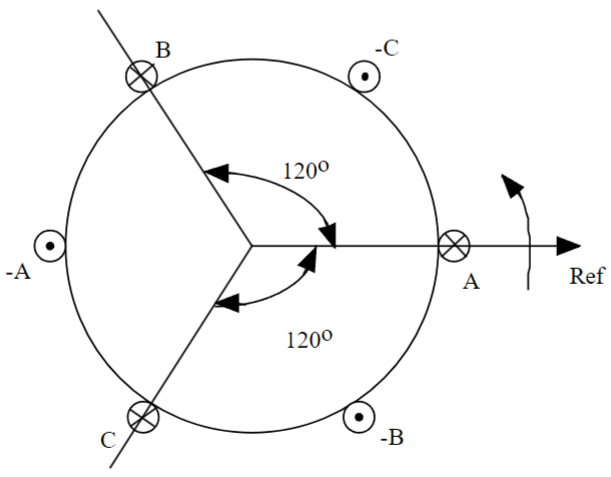

clearvars 

Line numbers may not exceed the last expression.

clc

Numeric computation is always recommended when it can solve the problem with acceptable precision. 

## Problem 1

### (a) Winding Function Diagrams for Windings A, B, and C   

Draw the winding functions for windings A, B, and C on the same sheet of paper.

#### **General Settings**

% Define the spatial angle from 0 to 360 degrees
T = 2*pi;
T_degree = rad2deg(T)

T_degree = 360

numOfPoints = 5000; % This affects precision of Fourier analysis 
theta = linspace(0, T, numOfPoints);
theta_degrees = linspace(0, T_degree, numOfPoints)

theta_degrees =          0    0.0720    0.1440    0.2160    0.2881    0.3601    0.4321    0.5041    0.5761    0.6481    0.7201    0.7922    0.8642    0.9362    1.0082    1.0802    1.1522    1.2242    1.2963    1.3683    1.4403    1.5123    1.5843    1.6563    1.7283    1.8004    1.8724    1.9444    2.0164    2.0884    2.1604    2.2324    2.3045    2.3765    2.4485    2.5205    2.5925    2.6645    2.7365    2.8086    2.8806    2.9526    3.0246    3.0966    3.1686    3.2406    3.3127    3.3847    3.4567    3.5287


#### **Counting Functions for Windings A, B, and C   **

% Initialize counting function to zero arrays
nA = zeros(size(theta));
nB = zeros(size(theta));
nC = zeros(size(theta));

% Define nA
nA(mod(theta, T) >= 0 & mod(theta, T) < T/2) = 1;
nA(mod(theta, T) >= T/2 & mod(theta, T) <= T) = 0;

**Explanation:**

- `mod(theta, T)`: This ensures that the function repeats every T. By applying `mod(theta, T)`, you're effectively folding the waveform to repeat from T to 2T.

- **First Condition**: For the interval 0≤θ≤T/2, the function returns `1`.

- **Second Condition**: For the interval T/2<θ≤T, the function returns `nA_pi - 1`.

% Define nB
% nB(theta >= 0 & theta < 120) = 0;
% nB(theta >= 120 & theta < 300) = 1;
% nB(theta >= 300 & theta <= 360) = 0;
% 
% % Define nC
% nC(theta >= 0 & theta < 60) = 1;
% nC(theta >= 60 & theta < 240) = 0;
% nC(theta >= 240 & theta <= 360) = 1;

% Define phase shift for iB and iC
phase_shift = 2*pi/3;

% Define iB as phase-shifted iA
nB = circshift(nA, [0, round(phase_shift/(2*pi) * length(theta))]);

% Define iC as phase-shifted iA by 2*phase_shift
nC = circshift(nA, [0, round(2*phase_shift/(2*pi) * length(theta))]);

#### **Winding Functions for Windings A, B, and C   **

% Define NA, NB, and NC 
NA = nA - mean(nA);
NB = nB - mean(nB);
NC = nC - mean(nC);

#### **Plot Counting Functions and Winding Functions A, B, and C   **

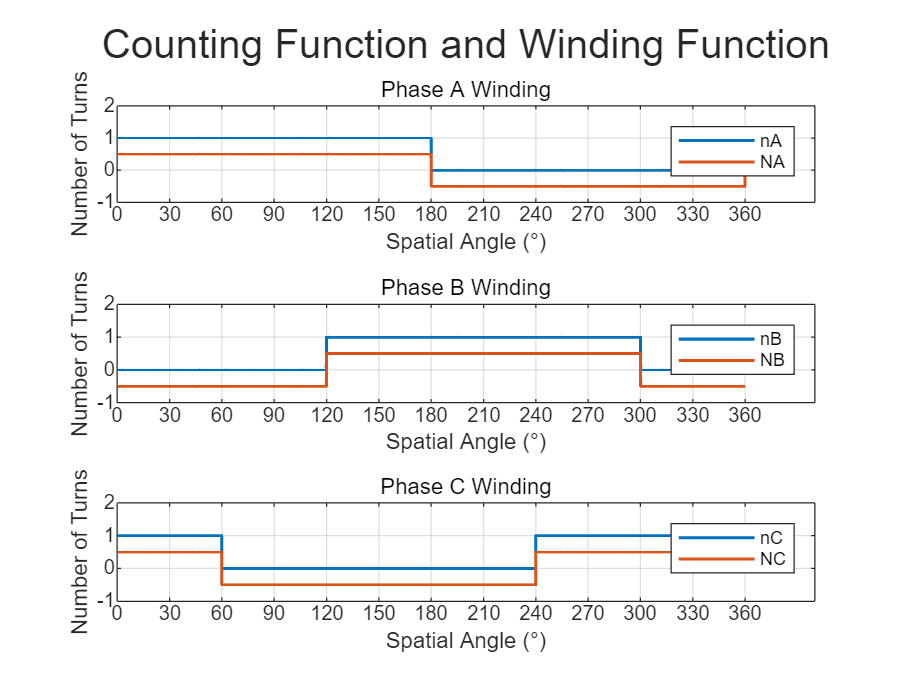

figure 

tiledlayout(3,1)
titleHandle = sgtitle("Counting Function and Winding Function");
titleHandle.FontSize = 16;

% First tile: nA and NA
nexttile;
plot(theta_degrees, nA, 'LineWidth', 1.2);
hold on;
plot(theta_degrees, NA, 'LineWidth', 1.2);
hold off;

ylim([-1 2]);
grid on;
xlabel("Spatial Angle (°)");
ylabel("Number of Turns");
subtitle("Phase A Winding");
legend('nA', 'NA');
xticks(0:30:360);

% Second tile: nB and NB
nexttile;
plot(theta_degrees, nB, 'LineWidth', 1.2);
hold on;
plot(theta_degrees, NB, 'LineWidth', 1.2);
hold off;

ylim([-1 2]);
grid on;
xlabel("Spatial Angle (°)");
ylabel("Number of Turns");
subtitle("Phase B Winding");
legend('nB', 'NB');
xticks(0:30:360);

% Third tile: nC and NC
nexttile;
plot(theta_degrees, nC, 'LineWidth', 1.2);
hold on;
plot(theta_degrees, NC, 'LineWidth', 1.2);
hold off;

ylim([-1 2]);
grid on;
xlabel("Spatial Angle (°)");
ylabel("Number of Turns");
subtitle("Phase C Winding");
legend('nC', 'NC');
xticks(0:30:360);


% Counting functions √
% Winding functions √

### (b) MMF of Windings A, B, and C Supplied by Three Phase Six Step Currents

Draw the MMF of each phase if the windings are supplied by three phase Six Step currents at ωt = 0°, 30° , 60° , 90° , 120°, ...

#### Three Phase Six Step Currents

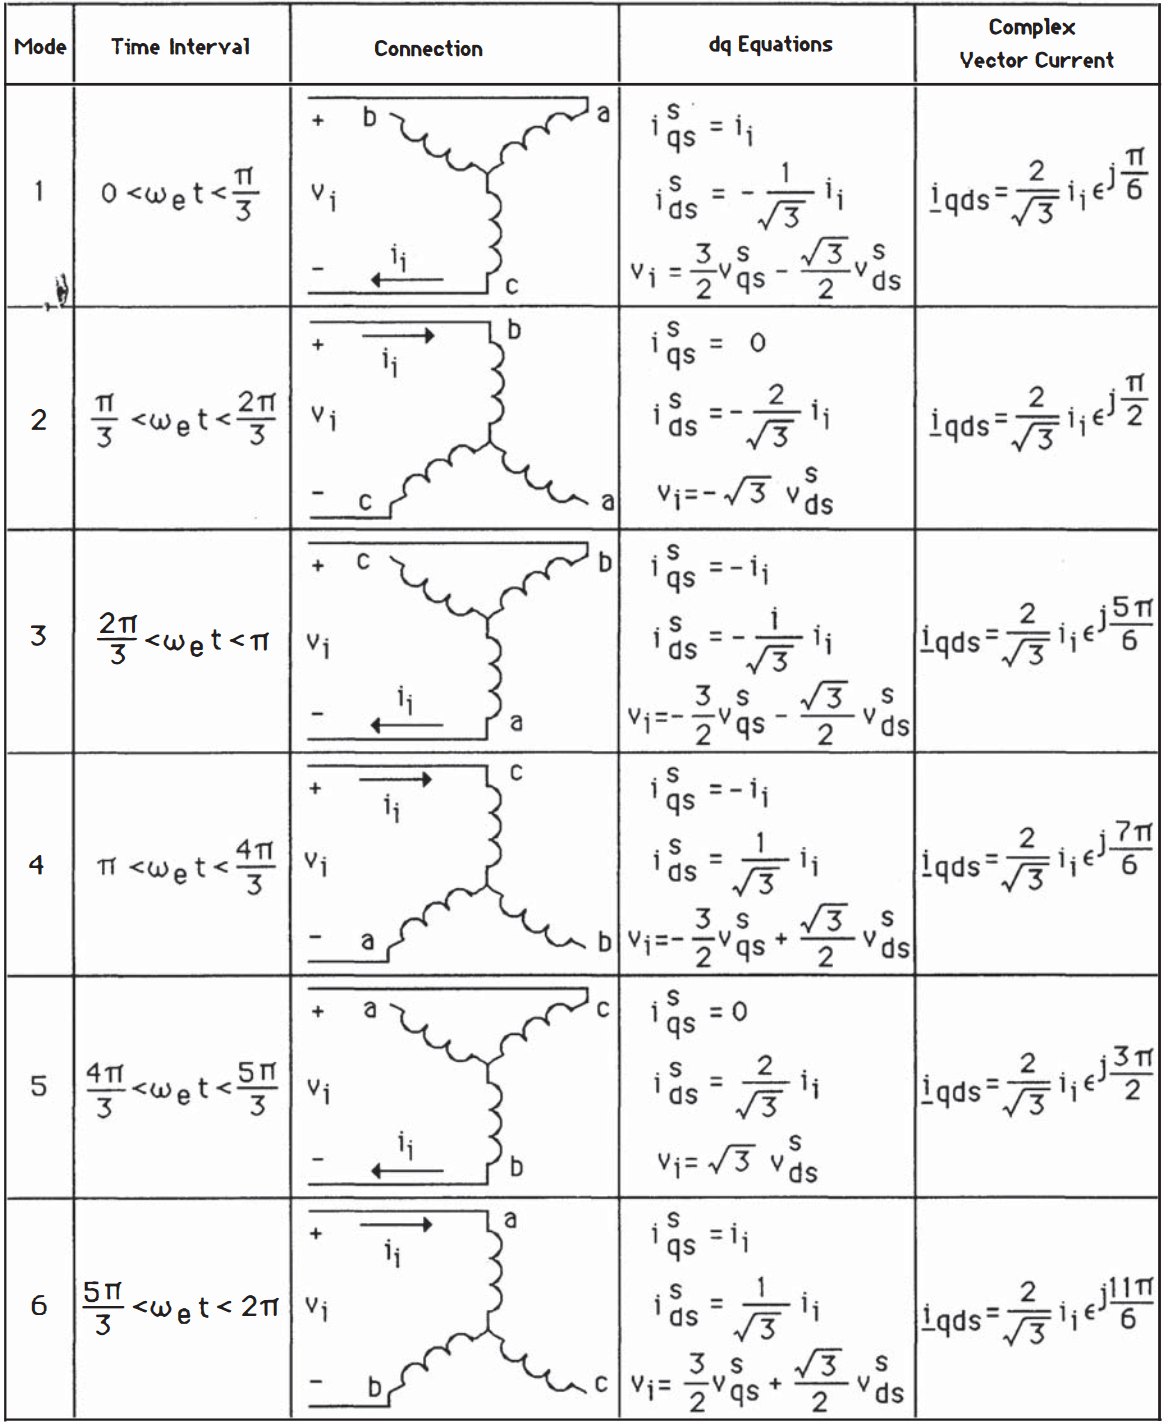

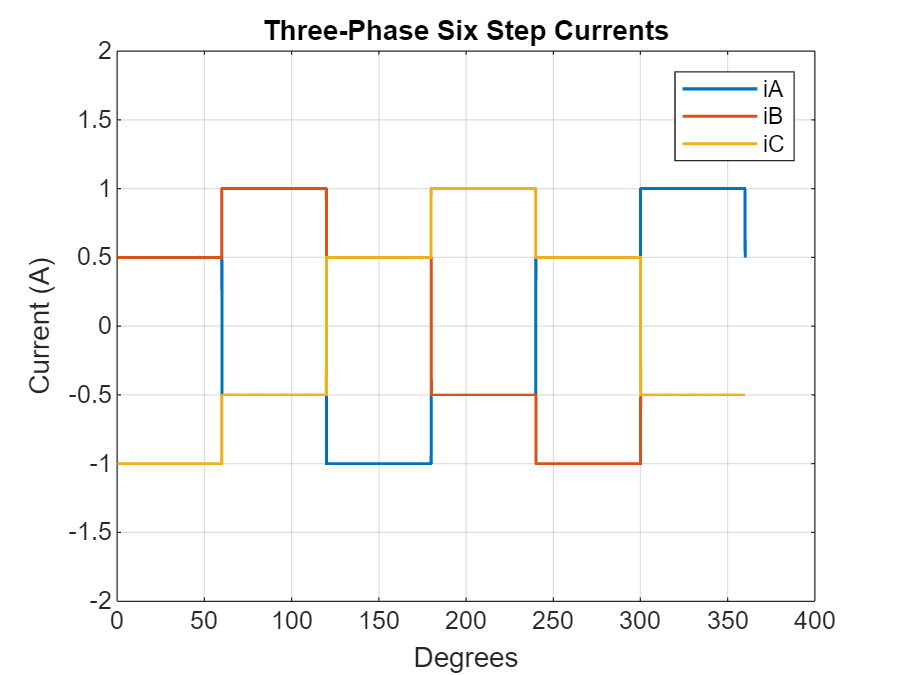

wt = linspace(0, T, numOfPoints);
wt_degrees = rad2deg(wt);

iA = zeros(size(wt));
iB = zeros(size(wt));
iC = zeros(size(wt));

% Define iA (piecewise function for phase A)
iA(mod(wt, 2*pi) >= 0 & mod(wt, 2*pi) < pi/3) = 1/2;
iA(mod(wt, 2*pi) >= pi/3 & mod(wt, 2*pi) < 2*pi/3) = -1/2;
iA(mod(wt, 2*pi) >= 2*pi/3 & mod(wt, 2*pi) < pi) = -1;
iA(mod(wt, 2*pi) >= pi & mod(wt, 2*pi) < 4*pi/3) = -1/2;
iA(mod(wt, 2*pi) >= 4*pi/3 & mod(wt, 2*pi) < 5*pi/3) = 1/2;
iA(mod(wt, 2*pi) >= 5*pi/3 & mod(wt, 2*pi) <= 2*pi) = 1;

% Define phase shift for iB and iC
phase_shift = 2*pi/3;

% Define iB as phase-shifted iA
iB = circshift(iA, [0, round(phase_shift/(2*pi) * length(wt))]);

% Define iC as phase-shifted iA by 2*phase_shift
iC = circshift(iA, [0, round(2*phase_shift/(2*pi) * length(wt))]);

% Ensure wt_degrees, iA, iB, and iC are defined
figure;
plot(wt_degrees, iA, ...        
     wt_degrees, iB, ...        
     wt_degrees, iC, 'LineWidth', 1.2);           
legend('iA', 'iB', 'iC');             
title('Three-Phase Six Step Currents');       
xlabel('Degrees');                             
ylabel('Current (A)');            
ylim([-2 2])
grid on;   

#### Three Phase Currents at Angle of Interest

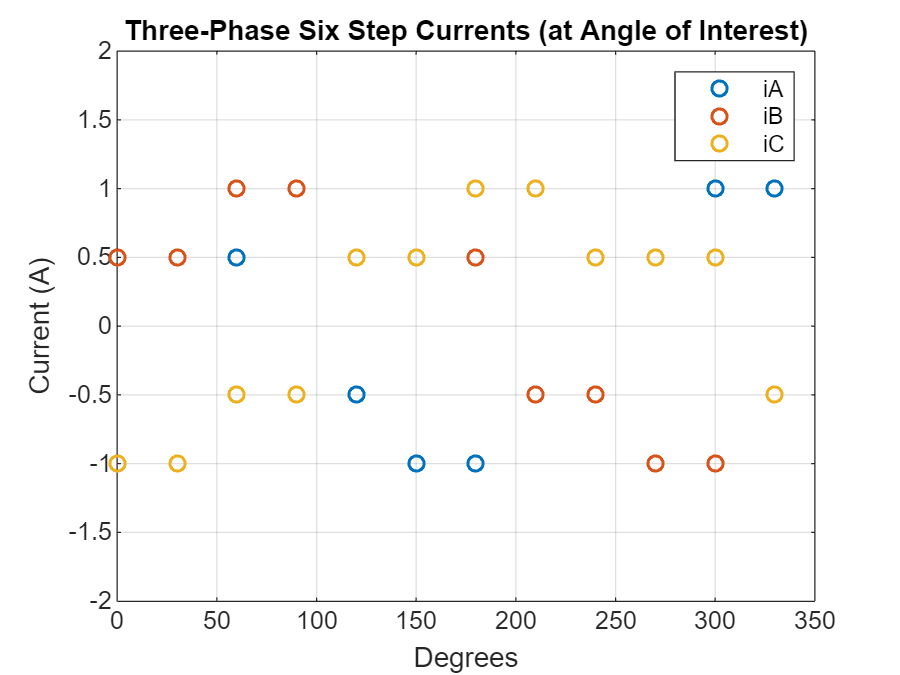

angleOfInterest = 0:30:330;

% Pre-allocate the index array
indices = zeros(size(angleOfInterest));

% Loop through each angle of interest and find the closest match in wt_degrees
for i = 1:length(angleOfInterest)
    [~, idx] = min(abs(wt_degrees - angleOfInterest(i))); % Find closest value
    indices(i) = idx; % Store the index of the closest value
end

iA_angleOfInterest = iA(indices);
iB_angleOfInterest = iB(indices);
iC_angleOfInterest = iC(indices);

% Ensure wt_degrees, iA, iB, and iC are defined
figure;
plot(wt_degrees(indices), iA_angleOfInterest, 'o', ...        
     wt_degrees(indices), iB_angleOfInterest, 'o', ...        
     wt_degrees(indices), iC_angleOfInterest, 'o', ...
     'LineWidth', 1.2);           
legend('iA', 'iB', 'iC');                      
title('Three-Phase Six Step Currents (at Angle of Interest)');       
xlabel('Degrees');                             
ylabel('Current (A)');     
ylim([-2 2])
grid on;   

#### Three Phase MMFs at Angles of Interest

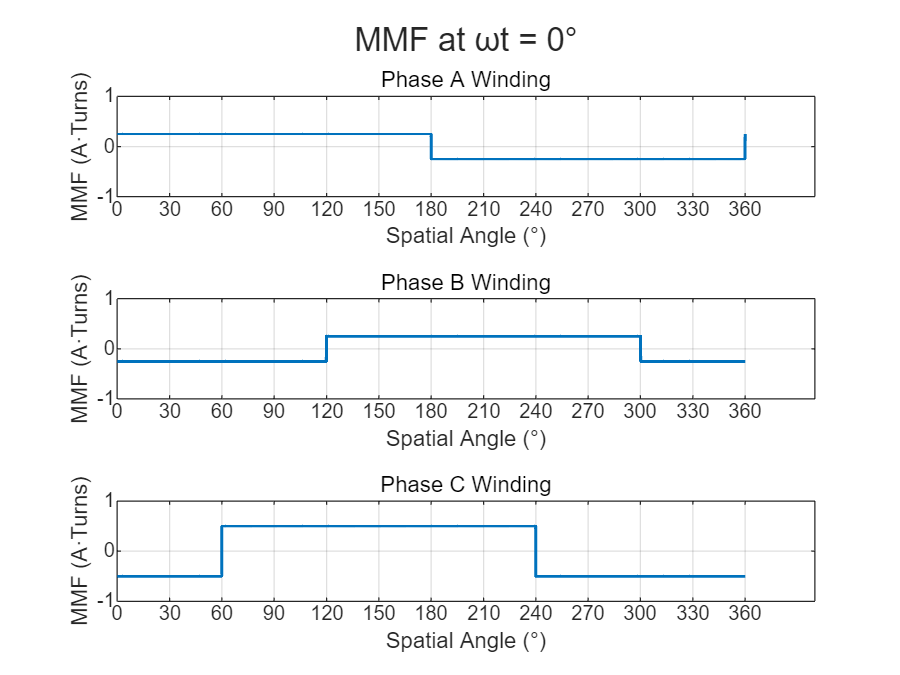

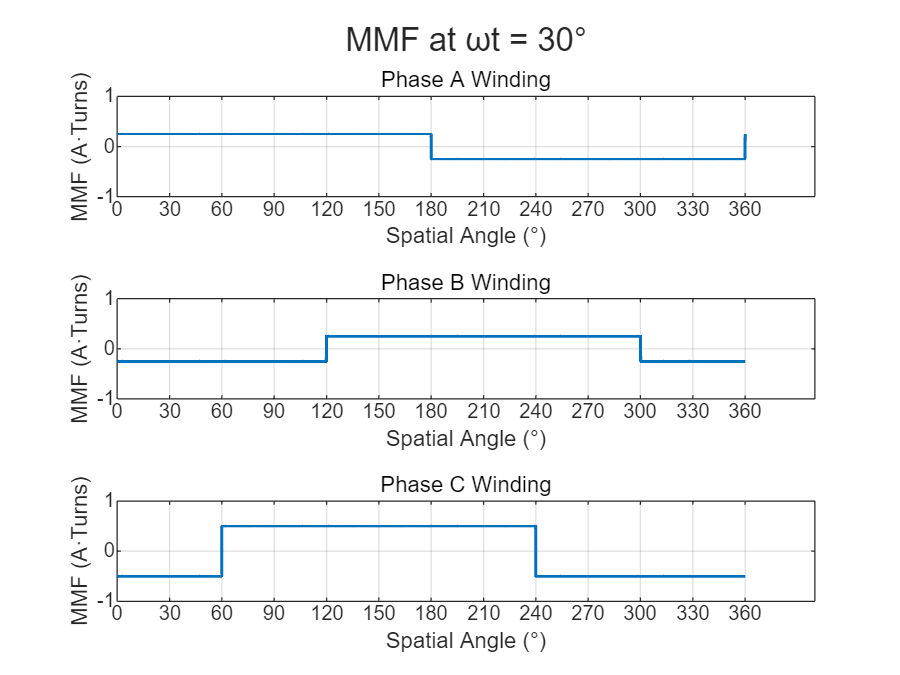

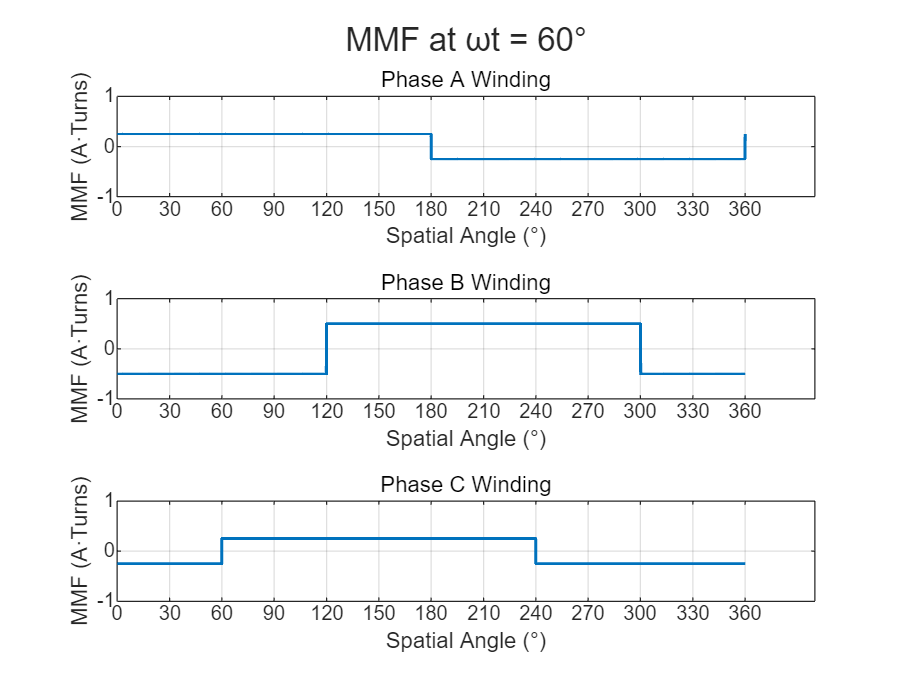

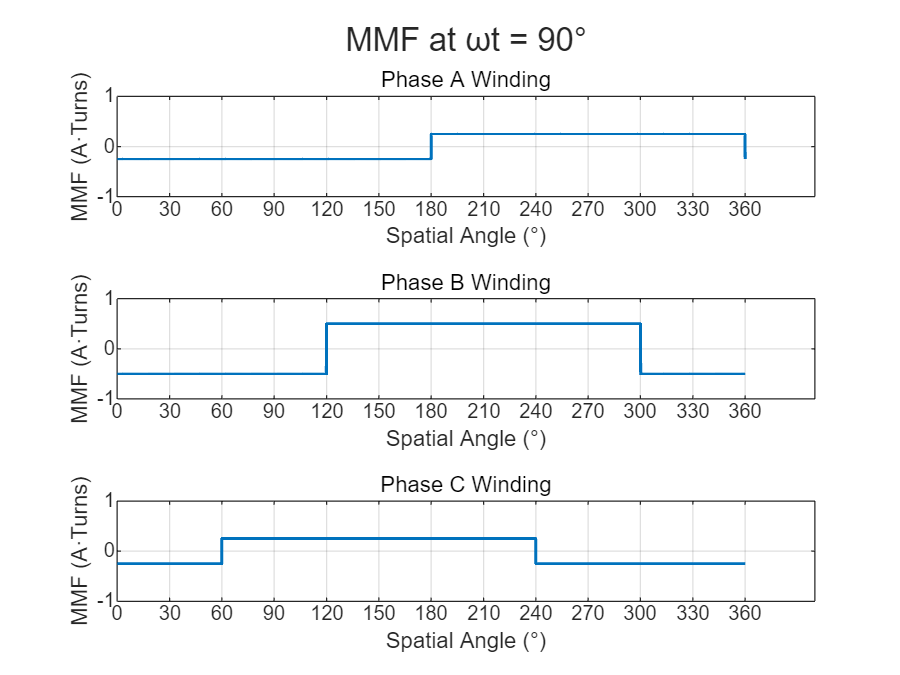

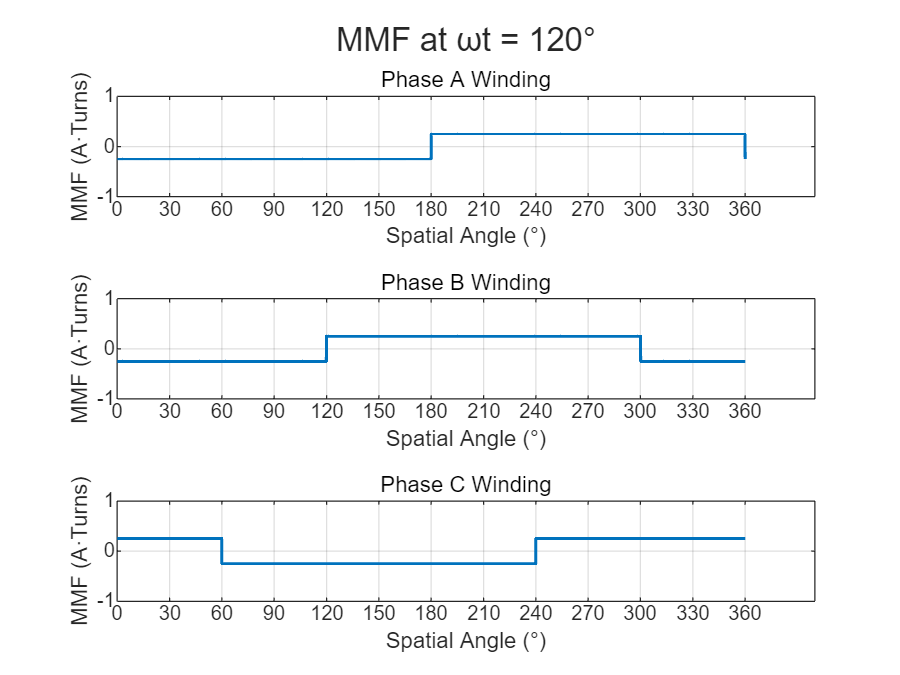

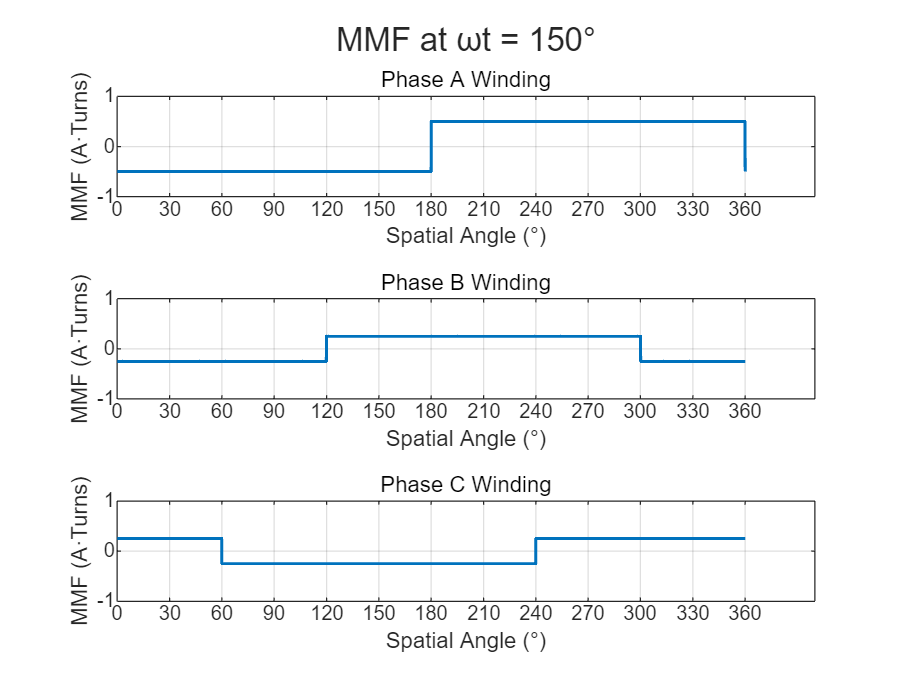

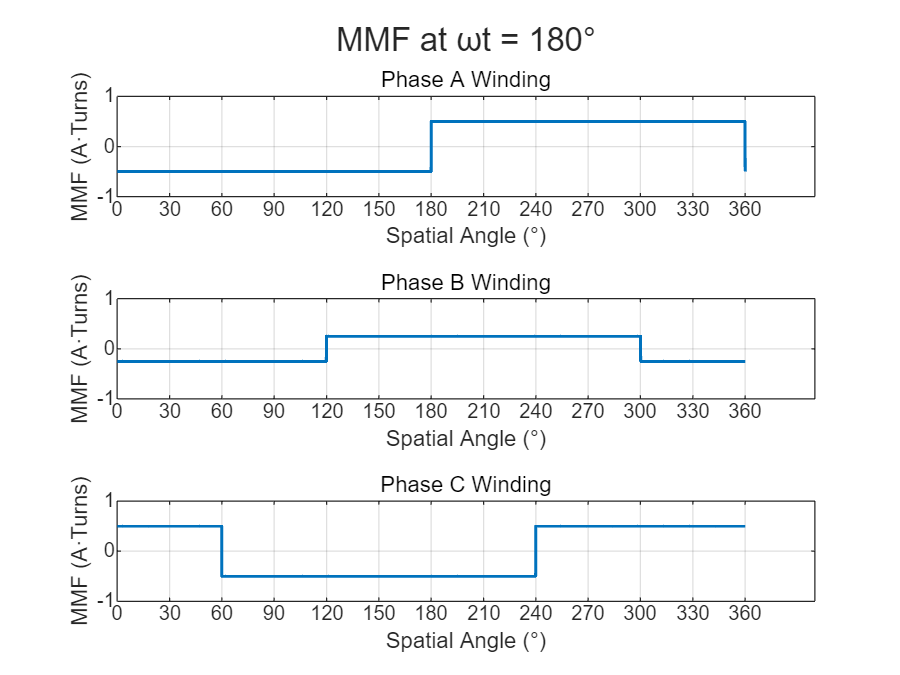

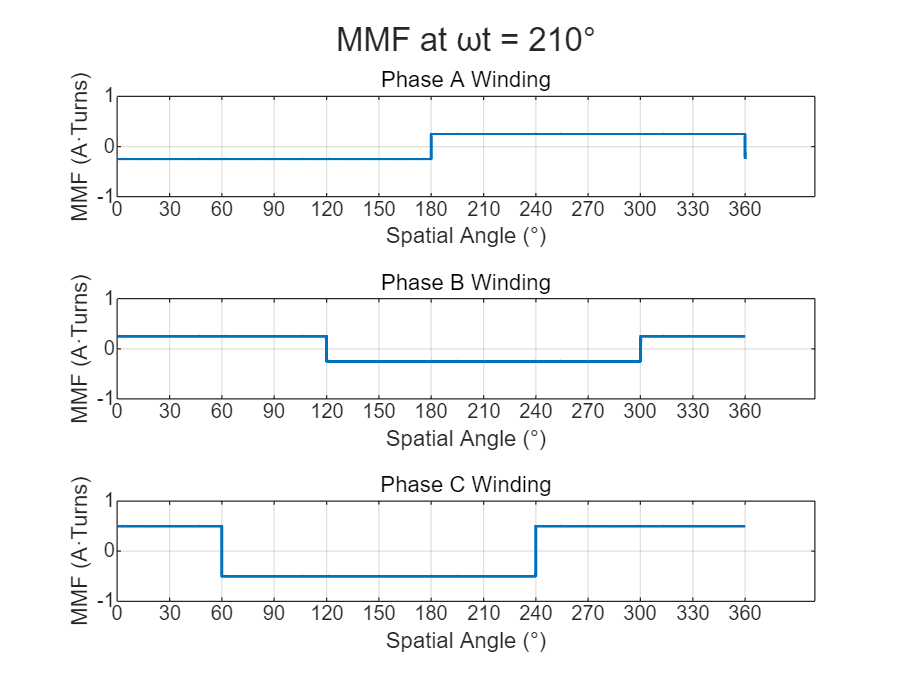

MMFA = NA .* iA_angleOfInterest';
MMFB = NB .* iB_angleOfInterest';
MMFC = NC .* iC_angleOfInterest';

for k = 1:length(angleOfInterest)
    
    figure;
    tiledlayout(3, 1);

    % Common title with current wt in degrees
    titleHandle = sgtitle(sprintf('MMF at ωt = %.0f°', angleOfInterest(k)));
    titleHandle.FontSize = 13;

    % Plot Phase A MMF
    nexttile;
    plot(wt_degrees, MMFA(k,:), 'LineWidth', 1.2);
    setPlotFormatting('Phase A Winding');
    
    % Plot Phase B MMF
    nexttile;
    plot(wt_degrees, MMFB(k,:), 'LineWidth', 1.2);
    setPlotFormatting('Phase B Winding');
    
    % Plot Phase C MMF
    nexttile;
    plot(wt_degrees, MMFC(k,:), 'LineWidth', 1.2);
    setPlotFormatting('Phase C Winding');
end 


function setPlotFormatting(subtitleText)
    % Helper function to set formatting for a plot
    ylim([-1 1]);
    grid on;
    xlabel("Spatial Angle (°)");
    ylabel("MMF (A·Turns)");
    subtitle(subtitleText);
    xticks(0:30:360); 
end

### (c) Total MMF at Angles of Interest

Find the total MMF at ωt = 0°, 30° , 60° , 90° , 120°, ...

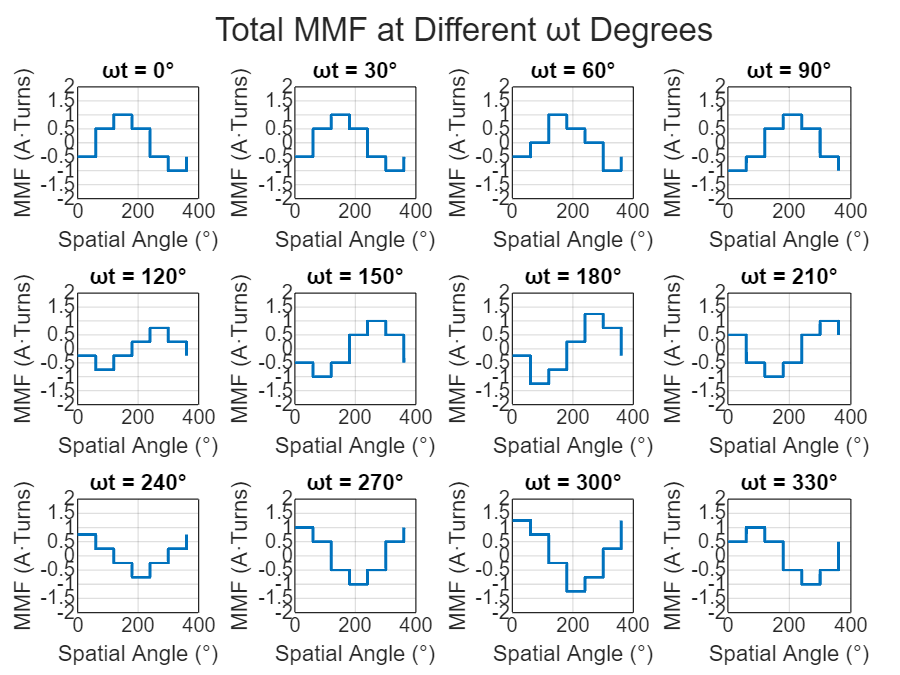

totalMMF = MMFA + MMFB + MMFC;

figure;
tiledlayout(3, 4, 'TileSpacing', 'Compact', 'Padding', 'Compact');

sgtitle('Total MMF at Different ωt Degrees');
titleHandle.FontSize = 13;

for k = 1:length(angleOfInterest)
    nexttile;
    plot(wt_degrees, totalMMF(k,:), 'LineWidth', 1.2);
    ylim([-2 2]);
    yticks(-2:0.5:2)
    grid on;
    xlabel("Spatial Angle (°)");
    ylabel("MMF (A·Turns)");
    title(sprintf('ωt = %.0f°', angleOfInterest(k)))
end 

## Problem 2

### (d) Fourier Series Analysis

#### Winding Functions Represented by Fourier Series

% a0 = (1/T)*int(expression, theta, 0, T);
% an = (2/T)*int(expression*cos(n*theta), theta, 0, T);
% bn = (2/T)*int(expression*sin(n*theta), theta, 0, T);

% DC component 
NA_a0 = mean(NA)

NA_a0 = -5.1816e-15


% Order of harmonics 
orderOfHarmonics = 1:13;

N = 1;
NA_bn_ref = 4./(orderOfHarmonics*pi)*N/2.*sin(orderOfHarmonics*pi/2)

NA_bn_ref =     0.6366    0.0000   -0.2122   -0.0000    0.1273    0.0000   -0.0909   -0.0000    0.0707    0.0000   -0.0579   -0.0000    0.0490



% Initialization 
NA_an = zeros(size(orderOfHarmonics));
NA_bn = zeros(size(orderOfHarmonics));

for n = 1:length(orderOfHarmonics)
    % Amplitude of even harmonics (cos terms)
    NA_an(n) = 2*mean(NA.*cos(n*theta));

    % Amplitude of odd harmonics (sin terms) 
    NA_bn(n) = 2*mean(NA.*sin(n*theta));
end 

% NA_an
% NA_bn
[NB_a0, NB_an, NB_bn] = computeHarmonicsAmplitude(NB, theta, orderOfHarmonics)

NB_a0 = -3.7291e-15

NB_an =    -0.5515   -0.0005   -0.0001   -0.0005    0.1100    0.0004   -0.0790   -0.0005   -0.0001   -0.0005    0.0499    0.0004   -0.0426


NB_bn =    -0.3182   -0.0005    0.2122    0.0005   -0.0637   -0.0000   -0.0454   -0.0005    0.0707    0.0005   -0.0290   -0.0000   -0.0244


[NC_a0, NC_an, NC_bn] = computeHarmonicsAmplitude(NC, theta, orderOfHarmonics)

NC_a0 = -3.7291e-15

NC_an =     0.5511    0.0001    0.0009    0.0001   -0.1104    0.0004    0.0786    0.0001    0.0009    0.0001   -0.0503    0.0004    0.0422


NC_bn =    -0.3189    0.0002    0.2122   -0.0002   -0.0630   -0.0000   -0.0461    0.0002    0.0707   -0.0002   -0.0283   -0.0000   -0.0251


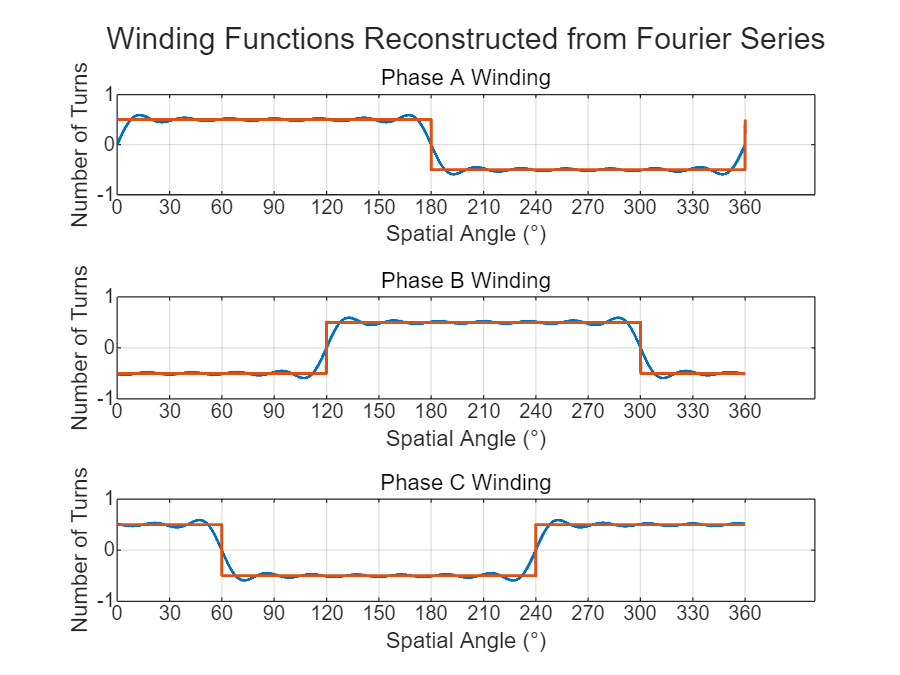


% Reconstructed winding function 
NA_rec = zeros(size(theta));
NB_rec = zeros(size(theta));
NC_rec = zeros(size(theta));

for n = 1:length(orderOfHarmonics)
        NA_rec = NA_rec + NA_an(n).*cos(n*theta) + NA_bn(n).*sin(n*theta);
        if n == orderOfHarmonics(end)
            NA_rec = NA_rec + NA_a0/2;
        end
end

NB_rec = reconstructFromFourierSeries(NB_a0, NB_an, NB_bn, theta, orderOfHarmonics);
NC_rec = reconstructFromFourierSeries(NC_a0, NC_an, NC_bn, theta, orderOfHarmonics);

function result = reconstructFromFourierSeries(a0, an, bn, theta, orderOfHarmonics)
    result = zeros(size(theta));
    for n = 1:length(orderOfHarmonics)
        result = result + an(n).*cos(n*theta) + bn(n).*sin(n*theta);
        if n == orderOfHarmonics(end)
            result = result + a0/2;
        end
    end
end 

figure 

tiledlayout(3,1)
titleHandle = sgtitle("Winding Functions Reconstructed from Fourier Series");
titleHandle.FontSize = 12;

nexttile;
plot(wt_degrees,NA_rec,wt_degrees,NA,"LineWidth",1.2)

subtitle("Phase A Winding");
ylabel("Number of Turns");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 

nexttile;
plot(wt_degrees,NB_rec,wt_degrees,NB,"LineWidth",1.2)

subtitle("Phase B Winding");
ylabel("Number of Turns");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 

nexttile;
plot(wt_degrees,NC_rec,wt_degrees,NC,"LineWidth",1.2)

subtitle("Phase C Winding");
ylabel("Number of Turns");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 


% Compare with original ones

**Plot Winding Function Odd Harmonics Spectrum**

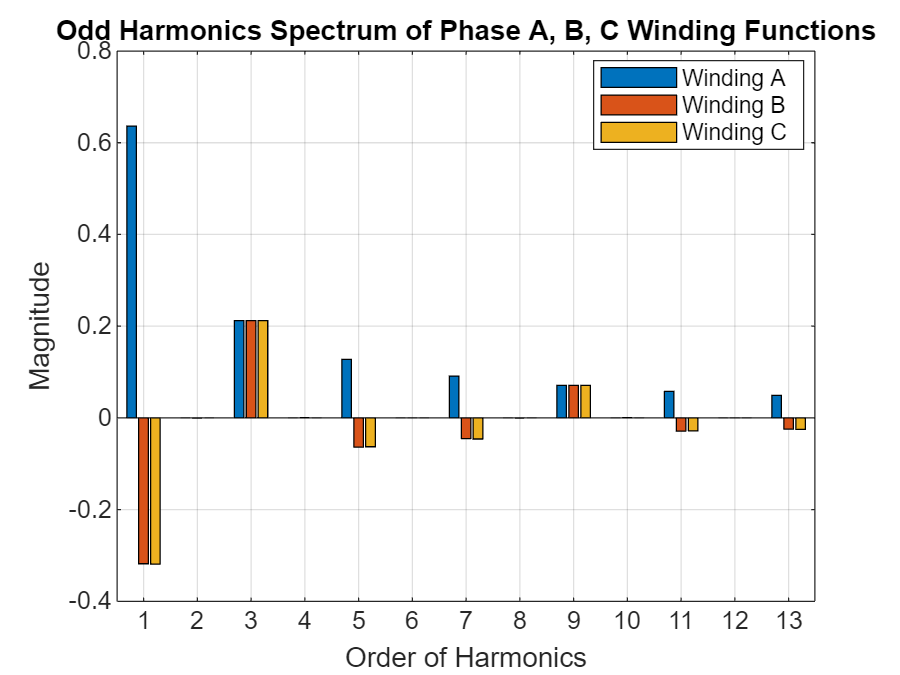

% numOfPhase = 3;
N_bn = [];
for k = 1:length(orderOfHarmonics)
    N_bn = [N_bn; NA_bn(k) NB_bn(k) NC_bn(k)]; 
end 

figure;
bar(N_bn, 'grouped'); % 'grouped' creates the grouped bar chart

% Labeling
xlabel('Order of Harmonics');
ylabel('Magnitude');
title('Odd Harmonics Spectrum of Phase A, B, C Winding Functions');

% Customize the x-tick labels
% set(gca, 'XTickLabel', {'Group 1', 'Group 2', 'Group 3'});
 
legend({'Winding A', 'Winding B', 'Winding C'}, 'Location', 'best');
grid on;

#### Six Step Currents Represented by Fourier Series

[iA_a0, iA_an, iA_bn] = computeHarmonicsAmplitude(iA, wt, orderOfHarmonics)

iA_a0 = 2.0000e-04

iA_an =     0.8270   -0.0001   -0.0000   -0.0000   -0.1652    0.0004    0.1183   -0.0001   -0.0000   -0.0000   -0.0750    0.0004    0.0638


iA_bn =    -0.4773    0.0001    0.0000   -0.0001   -0.0955    0.0000   -0.0682    0.0001    0.0000   -0.0001   -0.0434    0.0000   -0.0367


[iB_a0, iB_an, iB_bn] = computeHarmonicsAmplitude(iB, wt, orderOfHarmonics)

iB_a0 = 2.0000e-04

iB_an = 1.0e-03 *

   -0.4000    0.4000   -0.4000    0.4000   -0.4000    0.4000   -0.4000    0.4000   -0.4000    0.4000   -0.4000    0.4000   -0.4000


iB_bn =     0.9547    0.0005   -0.0000   -0.0005    0.1910    0.0000    0.1363    0.0005   -0.0000   -0.0005    0.0868    0.0000    0.0734


[iC_a0, iC_an, iC_bn] = computeHarmonicsAmplitude(iC, wt, orderOfHarmonics)

iC_a0 = 2.0000e-04

iC_an =    -0.8272   -0.0004   -0.0008   -0.0003    0.1650    0.0004   -0.1185   -0.0004   -0.0008   -0.0003    0.0748    0.0004   -0.0639


iC_bn =    -0.4770   -0.0006    0.0000    0.0006   -0.0958   -0.0000   -0.0678   -0.0006    0.0000    0.0006   -0.0438   -0.0000   -0.0363


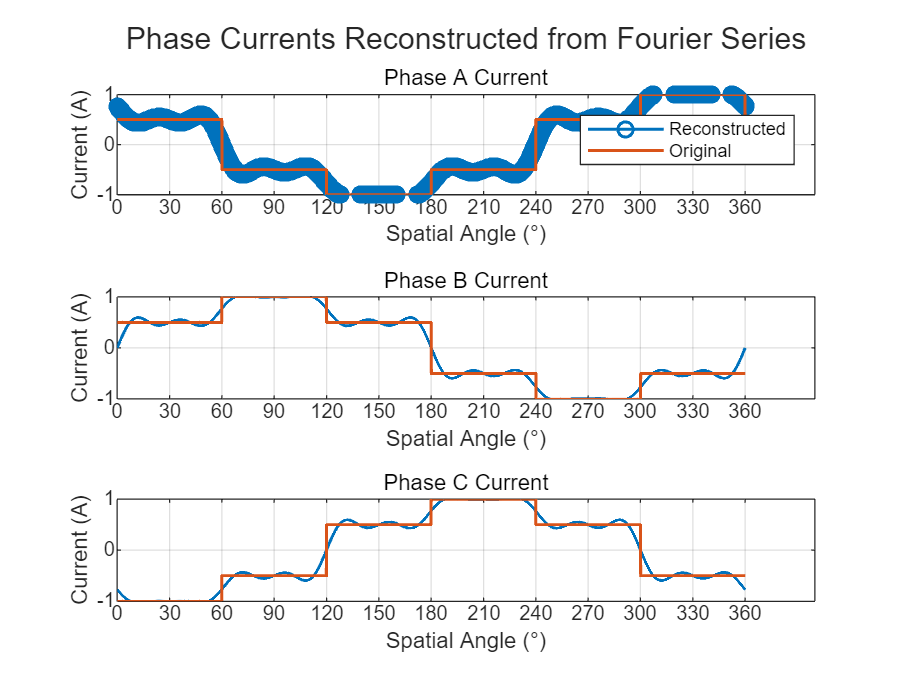


iA_rec = reconstructFromFourierSeries(iA_a0, iA_an, iA_bn, wt, orderOfHarmonics);
iB_rec = reconstructFromFourierSeries(iB_a0, iB_an, iB_bn, wt, orderOfHarmonics);
iC_rec = reconstructFromFourierSeries(iC_a0, iC_an, iC_bn, wt, orderOfHarmonics);

figure 

tiledlayout(3,1)
titleHandle = sgtitle("Phase Currents Reconstructed from Fourier Series");
titleHandle.FontSize = 12;

nexttile;
plot(wt_degrees,iA_rec, ...
    "DisplayName", "Reconstructed", ...
    "LineWidth",1.2, ...
    "Marker","o")
hold on 
plot(wt_degrees,iA, ...
    "DisplayName", "Original", ...
    "LineWidth",1.2)
hold off 

legend
subtitle("Phase A Current");
ylabel("Current (A)");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 

nexttile;
plot(wt_degrees,iB_rec,wt_degrees,iB,"LineWidth",1.2)

subtitle("Phase B Current");
ylabel("Current (A)");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 

nexttile;
plot(wt_degrees,iC_rec,wt_degrees,iC,"LineWidth",1.2)

subtitle("Phase C Current");
ylabel("Current (A)");
xlabel("Spatial Angle (°)");
xticks(0:30:360)
ylim([-1 1])
grid 

#### Phase MMF Represented by Fourier Series at Angles of Interest

iA_rec_angleOfInterest = iA_rec(indices);
iB_rec_angleOfInterest = iB_rec(indices);
iC_rec_angleOfInterest = iC_rec(indices);

MMFA_rec = NA_rec.*iA_rec_angleOfInterest'; % Transposed 
MMFB_rec = NB_rec.*iB_rec_angleOfInterest';
MMFC_rec = NC_rec.*iC_rec_angleOfInterest';

#### Total MMF Represented by Fourier Series at Angles of Interest

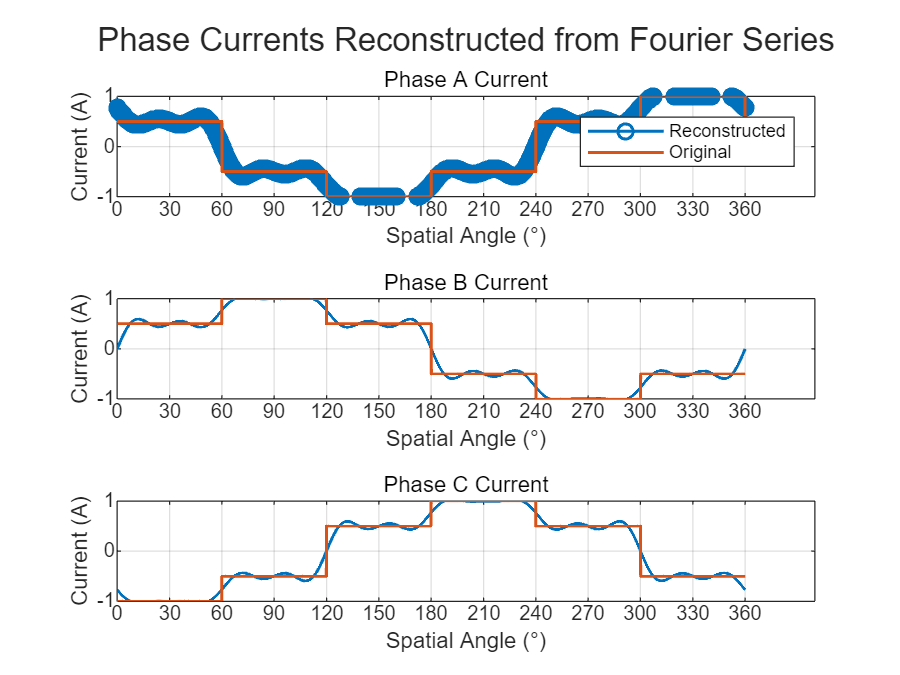

totalMMF_rec = MMFA_rec + MMFB_rec + MMFC_rec;

figure;
tiledlayout(3, 4, 'TileSpacing', 'Compact', 'Padding', 'Compact');

sgtitle('Total MMF at Different ωt Degrees');
titleHandle.FontSize = 13;

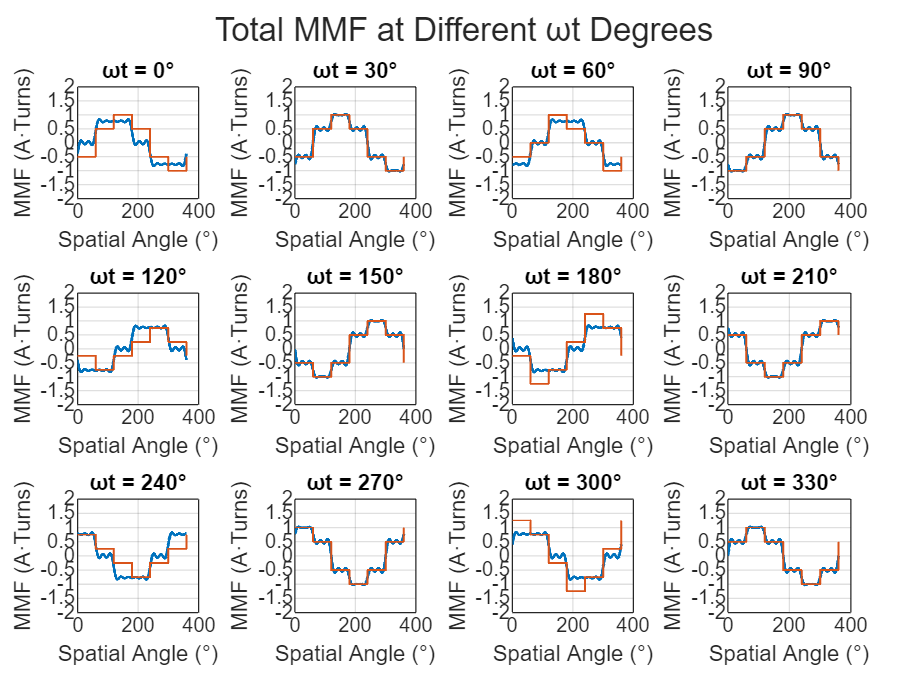


for k = 1:length(angleOfInterest)
    nexttile;
    plot(wt_degrees, totalMMF_rec(k,:), 'LineWidth', 1.2);
    hold on 
    plot(wt_degrees, totalMMF(k,:), 'LineWidth', 0.8);
    hold off 
    ylim([-2 2]);
    yticks(-2:0.5:2)
    grid on;
    xlabel("Spatial Angle (°)");
    ylabel("MMF (A·Turns)");
    title(sprintf('ωt = %.0f°', angleOfInterest(k)))
end 

#### Table

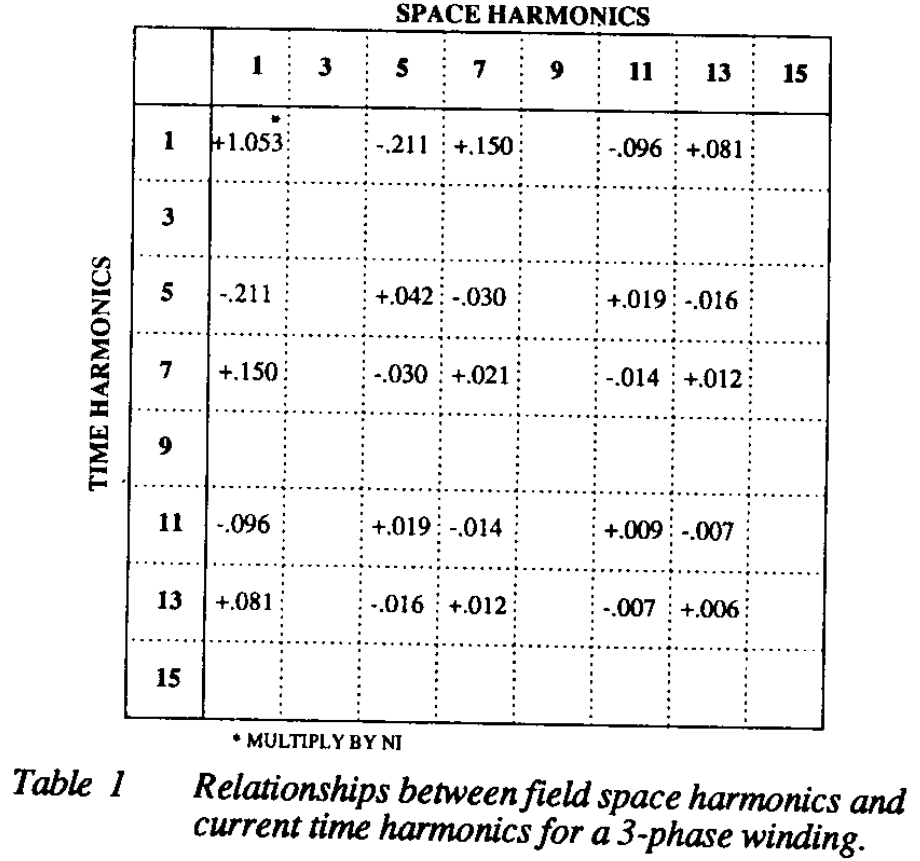

**Space Harmonics** (on the top horizontal axis): These refer to the harmonic components of the winding functions. The harmonics listed here include 1st, 3rd, 5th, 7th, 9th, 11th, 13th, and 15th order harmonics.

**Time Harmonics** (on the left vertical axis): These correspond to the harmonic components of the current in the winding. The harmonics listed include 1st, 3rd, 5th, 7th, 9th, 11th, 13th, and 15th order harmonics as well.

harmonic_matrix = zeros(orderOfHarmonics(end));

diagnal_harmonics = diag(NA_an.*iA_an + NB_an.*iB_an + NC_an.*iC_an);
cross_harmonics = NA_an.*iA_an' + NB_an.*iB_an' + NC_an.*iC_an';

harmonic_matrix(harmonic_matrix==0) = cross_harmonics(harmonic_matrix==0)

harmonic_matrix =    -0.4553    0.0002   -0.0004    0.0002    0.0916   -0.0000   -0.0646    0.0002   -0.0004    0.0002    0.0419   -0.0000   -0.0346
   -0.0004   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0002    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0004   -0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0911   -0.0000    0.0001   -0.0000   -0.0183   -0.0000    0.0129   -0.0000    0.0001   -0.0000   -0.0084   -0.0000    0.0069
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0650    0.0000   -0.0001    0.0000    0.0131   -0.0000   -0.0092    0.0000   -0.0001    0.0000    0.0060   -0.0000   -0.0049
   -0.0004   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0

% space = [2 1];
% time  = [1 2];
% 
% % space.*time' = [2 1].*[1;2]
% space.*time'
% % space.*time = [2 1].*[1 2] = [2 2]
% space.*time

% I'm confident with this method 
function [a0,an,bn] = computeHarmonicsAmplitude(expr,wt,orderOfHarmonics)
    
    a0 = mean(expr);
    
    % Initialization 
    an = zeros(size(orderOfHarmonics));
    bn = zeros(size(orderOfHarmonics));
    
    for n = 1:length(orderOfHarmonics)
        % Amplitude of even harmonics (cos terms)
        an(n) = 2*mean(expr.*cos(n*wt));
    
        % Amplitude of odd harmonics (sin terms) 
        bn(n) = 2*mean(expr.*sin(n*wt));
    end
end 